### ***1.3 - Fourier transform of a recorded signal***

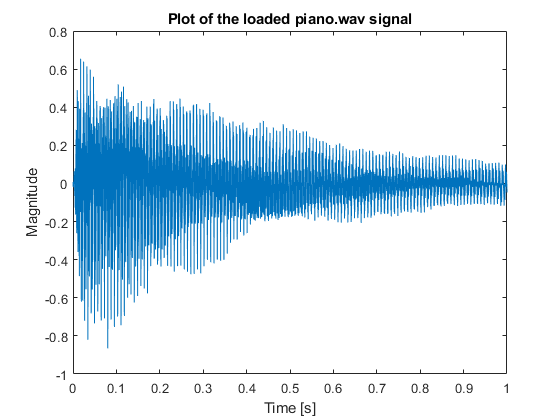

clear;
[piano, fs_loaded] = audioread([pwd filesep 'piano.wav']);
t = (1:length(piano))/fs_loaded;

figure(12)
plot(t, piano, '-')
xlim([0,1])
xlabel('Time [s]')
ylabel('Magnitude')
title('Plot of the loaded piano.wav signal')

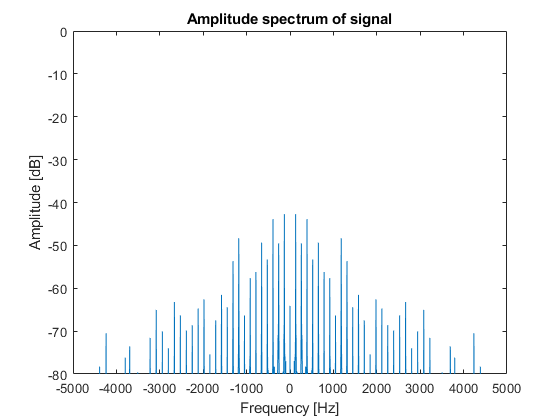

index =       203349
      205769


f0 = 130.4300


[Y_loaded, freq_loaded] = make_spectrum(piano, fs_loaded);

magdb_loaded = 20*log10(abs(Y_loaded));

figure(13)
plot(freq_loaded,magdb_loaded,'-')
xlim([-5000,5000]);
ylim([-80,0])
xlabel('Frequency [Hz]')
ylabel('Amplitude [dB]')
title('Amplitude spectrum of signal')

After probing the figure of the amplitude spectrum, the fundamental frequency (the one with the highest amplitude) seems to be approx. 130 Hz.

*Synthesis in frequency domain...*


% lets find the fundemental freq
index = find(magdb_loaded == max(magdb_loaded))

index =       203349
      205769


f_0 = freq_loaded(max(index))

f_0 = 130.4300

N = 99;
%Highest frequency at 99 * 130 = 12870 Hz
%Choosing a sampling frequency of 30000 Hz
fs = 30000;
T_0 = 2; %signal length of 2 seconds
N_0 = fs * T_0; %total number of samples

delta_f = fs/N_0; %frequency resolution
freq = -fs/2:delta_f:(fs/2 - delta_f);
Y = zeros(1,length(freq));

idx = all(rem(freq,130) == 0 & freq > 0, 1); %freq indeces of positive frequency multiples of f_0

idxs = find(idx); %On which of the original frequency indeces do these frequency values occur?

length(Y(idx))

ans = 115

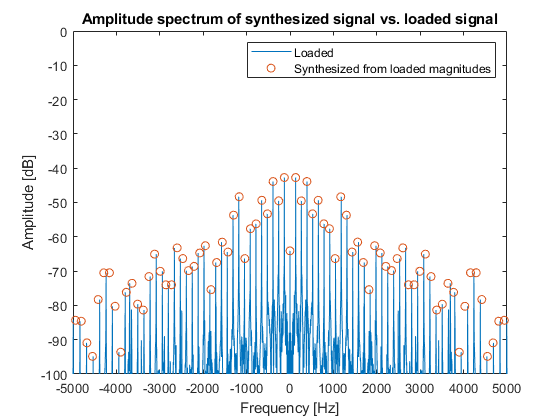


for k = 1:N 
   q = find(freq_loaded > (k*f_0 - 65) & freq_loaded < (k*f_0 + 65)); 
   %+/- 65 Hz in the interval of analysis because of non-perfect spectrum
   C = max(Y_loaded(q));
    
   i = idxs(k); %index of k multiple of fundamental frequency
   Y(i) = C; %assigning spectrum value to the frequency component
end

q_0 = find(freq_loaded == 0); 
C_0 = Y_loaded(q_0);   
i_0 = find(freq == 0); %index of k multiple of fundamental frequency
Y(i_0) = C_0; %assigning spectrum value to the frequency component

%The same probably needs to be done for negative frequencies

Y_pos = Y(1, (i_0 + 1):end);
Y_neg = conj(flip(Y_pos)); %Anti-symmetry of phase of sinusoids in negative frequencies
Y_dc = Y(i_0);

Y_complete = [Y_neg Y_dc Y_pos 0];

magdb = 20*log10(abs(Y_complete+(10e-12)));

figure(15)
plot(freq_loaded,magdb_loaded,'-')
hold on
plot(freq,magdb,'o')
hold off
xlim([-5000,5000]);
ylim([-100,0])
xlabel('Frequency [Hz]')
ylabel('Amplitude [dB]')
title('Amplitude spectrum of synthesized signal vs. loaded signal')
legend('Loaded','Synthesized from loaded magnitudes')

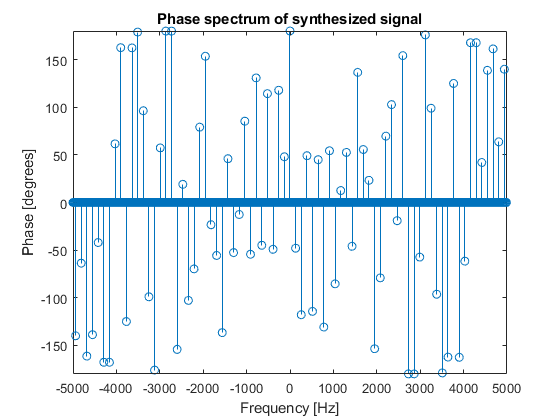


figure(16)
stem(freq,angle(Y_complete)*180/pi,'o')
xlim([-5000,5000]);
ylim([-180,180])
xlabel('Frequency [Hz]')
ylabel('Phase [degrees]')
title('Phase spectrum of synthesized signal')

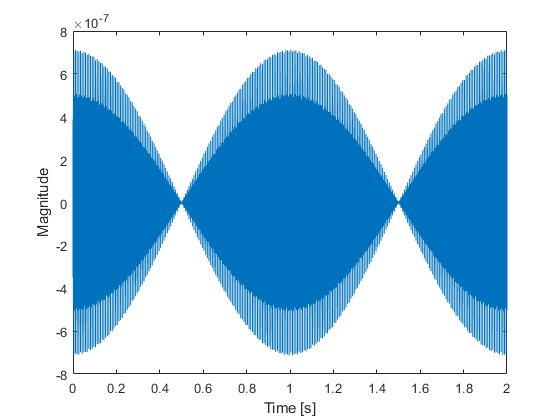


%IFFT
y = ifft((Y_complete)); 
%The complex values are vanishingly small, so the real part will be used
%below

t_y = (1:length(y))/fs;

figure(17)
plot(t_y,real(y))
xlim([0,2])
xlabel('Time [s]')
ylabel('Magnitude')



%What is going on...?